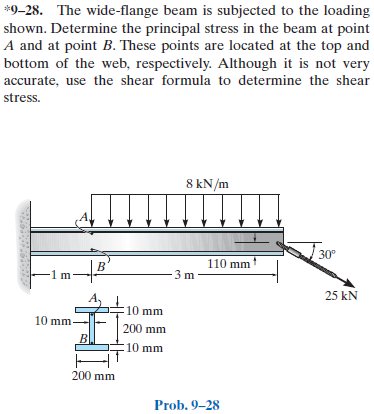

[https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-9-problem-28P-solution-9780136022305](https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-9-problem-28P-solution-9780136022305) 

# assumptions

u = symunit;
old.assum = assumptions;
clearassum;

# load data

theta = 30*u.deg;
[P M V] = deal(default_struct('a', 'b'));
[Y Q t] = deal(P);
[sigma_axial sigma_bending tau_shear] = deal(P);
[sigmax sigmay tauxy] = deal(P);
[sigmaxp sigmayp tauxyp thetap] = deal(P);
[sigmaxs sigmays tauxys thetas] = deal(P);

# beam

b = beam;
b = b.add('reaction', 'force', 'R', 0);
b = b.add('reaction', 'moment', 'M', 0);
b = b.add('concentrated', 'force', -25*u.kN*sin(theta), 4*u.m);
b = b.add('distributed', 'force', -8*u.kN/u.m, [1 4]*u.m);
b.L = 4*u.m;

# section properties

yc = [110-10/2 0 -110+10/2]*u.mm;
Ac = [200*10 10*200 200*10]*u.mm^2;
Ic = [200*10^3 10*200^3 200*10^3]/sym(12)*u.mm^4;
[yn Qn In] = beam.neutral_axis(yc, Ac, Ic);
b.I = rewrite(sum(In), u.m);
A = sum(Ac);

# solution

[y dy m v w rs ra hs ha] = b.elastic_curve('Mode', 'factor');

# elastic curve

y

$$y(x) = \left\{ \begin{array}{cl} \frac{625000\,x^{2}\,\left(73\,x-660\,m\right)}{381\,\text{E}}\,\frac{\mathrm{kN}}{m^{4}} & \text{ if }x\leq m\\ -\frac{625000\,\left(4\,x^{4}-89\,x^{3}\,m+684\,x^{2}\,m^{2}-16\,x\,m^{3}+4\,m^{4}\right)}{381\,\text{E}}\,\frac{\mathrm{kN}}{m^{5}} & \text{ if }m<x \end{array}\right.$$

dy

$$dy(x) = \left\{ \begin{array}{cl} \frac{625000\,x\,\left(73\,x-440\,m\right)}{127\,\text{E}}\,\frac{\mathrm{kN}}{m^{4}} & \text{ if }x\leq m\\ -\frac{625000\,\left(16\,x^{3}-267\,x^{2}\,m+1368\,x\,m^{2}-16\,m^{3}\right)}{381\,\text{E}}\,\frac{\mathrm{kN}}{m^{5}} & \text{ if }m<x \end{array}\right.$$

m

$$m(x) = \left\{ \begin{array}{cl} \frac{73\,x-220\,m}{2}\,\mathrm{kN} & \text{ if }x<m\\ -\frac{\left(x-4\,m\right)\,\left(8\,x-57\,m\right)}{2}\,\frac{\mathrm{kN}}{m} & \text{ if }m\leq x \end{array}\right.$$

v

$$v(x) = \left\{ \begin{array}{cl} \frac{73}{2}\,\mathrm{kN} & \text{ if }x<m\\ -\frac{16\,x-89\,m}{2}\,\frac{\mathrm{kN}}{m} & \text{ if }m\leq x \end{array}\right.$$

w

$$w(x) = \left\{ \begin{array}{cl} 0 & \text{ if }x<m\\ -8\,\frac{\mathrm{kN}}{m} & \text{ if }m\leq x \end{array}\right.$$

# reactions and hinges

ra_vpa = vpa(ra) %#ok<NASGU> 

$$ra\_vpa = \left(\begin{array}{cc} M & 110.0\,\mathrm{kN}\,m\\ R & 36.5\,\mathrm{kN} \end{array}\right)$$

ha

 
ha =
 
Empty sym: 0-by-2
 


# shear and moment diagram

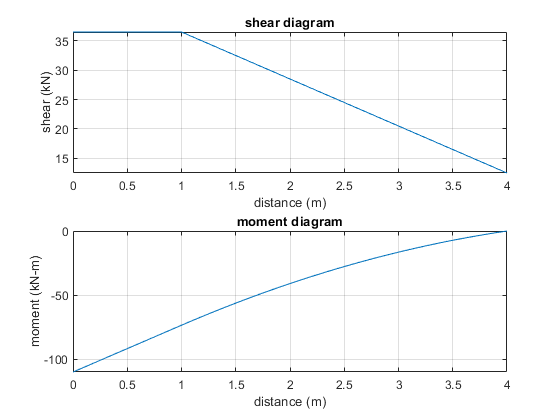

beam.shear_moment(m, v, [0 b.L], {'kN' 'm'});

# loads at points A

P.a = 25*u.kN*cos(theta);
P_a = vpa(P.a, 4) %#ok<NASGU> 

$$P\_a = 21.65\,\mathrm{kN}$$

M.a = m(u.m);
M_a = vpa(M.a) %#ok<NASGU> 

$$M\_a = -73.5\,\mathrm{kN}\,m$$

V.a = v(u.m);
V_a = vpa(V.a) %#ok<NASGU> 

$$V\_a = 36.5\,\mathrm{kN}$$

# loads at points B

[P.b M.b V.b] = deal(P.a, M.a, V.a);
P_b = vpa(P.b, 4) %#ok<NASGU> 

$$P\_b = 21.65\,\mathrm{kN}$$

M_b = vpa(M.b) %#ok<NASGU> 

$$M\_b = -73.5\,\mathrm{kN}\,m$$

V_b = vpa(V.b) %#ok<NASGU> 

$$V\_b = 36.5\,\mathrm{kN}$$

# stresses at point A

% ------------
% axial stress
% ------------
sigma_axial.a = rewrite(P.a/A, u.MPa);
sigma_axial_a = vpa(sigma_axial.a, 3) %#ok<NASGU> 

$$sigma\_axial\_a = 3.61\,\mathrm{MPa}$$

% --------------
% bending stress
% --------------
Y.a = 100*u.mm;
b.I = rewrite(b.I, u.mm);
sigma_bending.a = rewrite(-M.a*Y.a/b.I, u.MPa);
sigma_bending_a = vpa(sigma_bending.a, 5) %#ok<NASGU> 

$$sigma\_bending\_a = 144.69\,\mathrm{MPa}$$

% ------------
% shear stress
% ------------
Q.a = Qn(1);
t.a = 10*u.mm;
tau_shear.a = rewrite(-V.a*Q.a/(b.I*t.a), u.MPa);
tau_shear_a = vpa(tau_shear.a, 4) %#ok<NASGU> 

$$tau\_shear\_a = -15.09\,\mathrm{MPa}$$

# stresses at point B

% ------------
% axial stress
% ------------
sigma_axial.b = sigma_axial.a;
sigma_axial_b = vpa(sigma_axial.b, 3) %#ok<NASGU> 

$$sigma\_axial\_b = 3.61\,\mathrm{MPa}$$

% --------------
% bending stress
% --------------
Y.b = -Y.a;
sigma_bending.b = rewrite(-M.b*Y.b/b.I, u.MPa);
sigma_bending_b = vpa(sigma_bending.b, 5) %#ok<NASGU> 

$$sigma\_bending\_b = -144.69\,\mathrm{MPa}$$

% ------------
% shear stress
% ------------
Q.b = Q.a;
t.b = t.a;
tau_shear.b = rewrite(-V.b*Q.b/(b.I*t.b), u.MPa);
tau_shear_b = vpa(tau_shear.b, 4) %#ok<NASGU> 

$$tau\_shear\_b = -15.09\,\mathrm{MPa}$$

# mohr stresses at point A

sigmax.a = sigma_axial.a+sigma_bending.a;
sigmax_a = vpa(sigmax.a, 5) %#ok<NASGU> 

$$sigmax\_a = 148.29\,\mathrm{MPa}$$

sigmay.a = sym(0);
sigmay_a = sigmay.a %#ok<NASGU> 

$$sigmay\_a = 0$$

tauxy.a = tau_shear.a;
tauxy_a = vpa(tauxy.a, 4) %#ok<NASGU> 

$$tauxy\_a = -15.09\,\mathrm{MPa}$$

[sigmaxp.a sigmayp.a tauxyp.a thetap.a] = beam.principal(sigmax.a, sigmay.a, tauxy.a);
[sigmaxs.a sigmays.a tauxys.a thetas.a] = beam.max_shear(sigmax.a, sigmay.a, tauxy.a);

# mohr stresses at point B

sigmax.b = sigma_axial.b+sigma_bending.b;
sigmax_b = vpa(sigmax.b, 5) %#ok<NASGU> 

$$sigmax\_b = -141.08\,\mathrm{MPa}$$

sigmay.b = sym(0);
sigmay_b = sigmay.b %#ok<NASGU> 

$$sigmay\_b = 0$$

tauxy.b = tau_shear.b;
tauxy_b = vpa(tauxy.b, 4) %#ok<NASGU> 

$$tauxy\_b = -15.09\,\mathrm{MPa}$$

[sigmaxp.b sigmayp.b tauxyp.b thetap.b] = beam.principal(sigmax.b, sigmay.b, tauxy.b);
[sigmaxs.b sigmays.b tauxys.b thetas.b] = beam.max_shear(sigmax.b, sigmay.b, tauxy.b);

# mohr's circle for point A

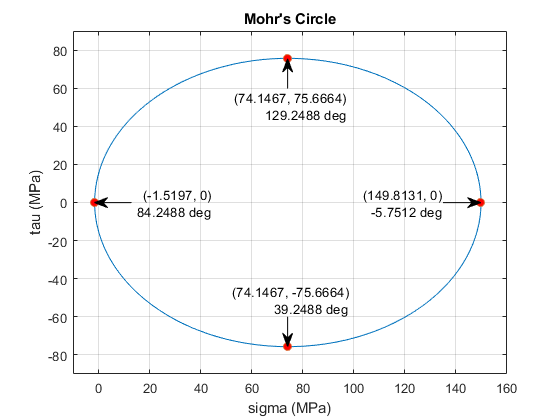

beam.mohr_plot(sigmax.a, sigmay.a, tauxy.a, {'MPa'});
axis([-10 160 -90 90]);
xvals = double(separateUnits([sigmaxp.a sigmaxs.a]));
yvals = double(separateUnits([tauxyp.a tauxys.a]));
thetavals = double(separateUnits([thetap.a thetas.a]));
hold on;
plot(xvals, yvals, 'o', 'MarkerFaceColor', 'r');
for k = 1:4
  switch k
    case 1
      x1 = 135;
      y1 = 0;
    case 2
      x1 = 13;
      y1 = 0;
    case 3
      x1 = xvals(3);
      y1 = -60;
    case 4
      x1 = xvals(4);
      y1 = 60;
  end
  [x1 y1] = ds2nfu(x1, y1);
  [x2 y2] = ds2nfu(xvals(k), yvals(k));
  text_str = {['(' num2str(xvals(k)) ', ' num2str(yvals(k)) ')']
              [num2str(thetavals(k)) ' deg']};
  annotation('textarrow', [x1 x2], [y1 y2], 'String', text_str);
end

# mohr's circle for point B

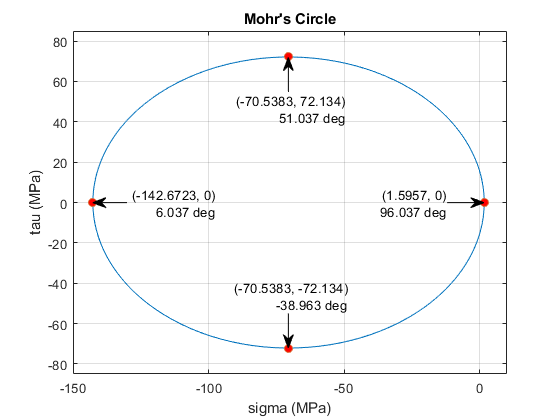

beam.mohr_plot(sigmax.b, sigmay.b, tauxy.b, {'MPa'});
axis([-150 10 -85 85]);
xvals = double(separateUnits([sigmaxp.b sigmaxs.b]));
yvals = double(separateUnits([tauxyp.b tauxys.b]));
thetavals = double(separateUnits([thetap.b thetas.b]));
hold on;
plot(xvals, yvals, 'o', 'MarkerFaceColor', 'r');
for k = 1:4
  switch k
    case 1
      x1 = -130;
      y1 = 0;
    case 2
      x1 = -12;
      y1 = 0;
    case 3
      x1 = xvals(3);
      y1 = -55;
    case 4
      x1 = xvals(4);
      y1 = 55;
  end
  [x1 y1] = ds2nfu(x1, y1);
  [x2 y2] = ds2nfu(xvals(k), yvals(k));
  text_str = {['(' num2str(xvals(k)) ', ' num2str(yvals(k)) ')']
              [num2str(thetavals(k)) ' deg']};
  annotation('textarrow', [x1 x2], [y1 y2], 'String', text_str);
end

# clean up

addvar(y);
assume(old_assum);
clear old_assum;
clear ra_vpa;
clear P_a M_a V_a;
clear P_b M_b V_b;
clear sigma_axial_a sigma_bending_a tau_shear_a;
clear sigma_axial_b sigma_bending_b tau_shear_b;
clear sigmax_a sigmay_a tauxy_a;
clear sigmax_b sigmay_b tauxy_b;
clear xvals yvals thetavals k x1 y1 x2 y2 text_str;